Note: Need to download pHRIWARE package:

`https://github.com/bryan91/pHRIWARE`

clear all
% D-H table of the asymmetric model
% AS_DH = [theta d a alpha]
syms q1 q2 q3 q4 q5 q6;

% AS_DH_from_paper = [q1      0.040   0     0;
%                   q2+13*pi/30 0    0.120     pi/2;
%                   q3-23*pi/30 0    0.194 0;
%                   q4      0.176  0    -pi/2;
%                   q5+pi/2 0    0     pi/2;
%                   q6      0    0     pi/2]

AS_DH =[q1          0.040 0     pi/2;
        q2+13*pi/30 0     0.120 0;
        q3-23*pi/30 0     0.194 -pi/2;
        q4          0.176 0     pi/2;
        q5+pi/2     0     0     pi/2;
        q6          0     0     0]

$$AS\_DH = \left(\begin{array}{cccc} q_{1} & \frac{1}{25} & 0 & \frac{\pi }{2}\\ q_{2}+\frac{13\,\pi }{30} & 0 & \frac{3}{25} & 0\\ q_{3}-\frac{23\,\pi }{30} & 0 & \frac{97}{500} & -\frac{\pi }{2}\\ q_{4} & \frac{22}{125} & 0 & \frac{\pi }{2}\\ q_{5}+\frac{\pi }{2} & 0 & 0 & \frac{\pi }{2}\\ q_{6} & 0 & 0 & 0 \end{array}\right)$$


L(1) = Link('d', 0.04, 'a', 0, 'alpha', pi/2, 'offset', 0);
L(2) = Link('d', 0, 'a', 0.12, 'alpha', 0, 'offset', (13/30)*pi);
L(3) = Link('d', 0, 'a', 0.194, 'alpha', -pi/2, 'offset', -(23/30)*pi);
L(4) = Link('d', 0.176, 'a', 0, 'alpha', pi/2, 'offset', 0);
L(5) = Link('d', 0, 'a', 0, 'alpha', pi/2, 'offset', pi/2); 
L(6) = Link('d', 0, 'a', 0, 'alpha', 0, 'offset', 0);
L(7) = Link('d', 0.15, 'a', 0, 'alpha', 0, 'offset', 0);
As_Robot = SerialLink(L);
As_Robot.name = 'Asymmetric Robot';


Collision with SerialLink

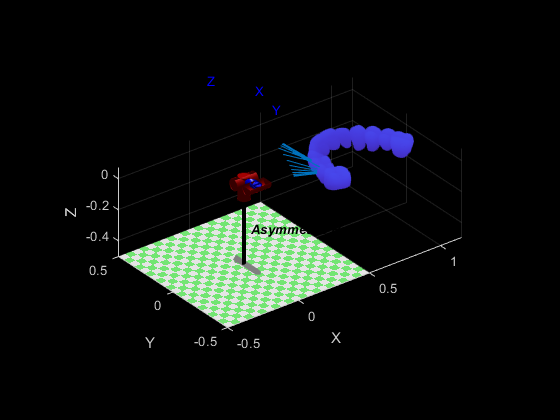

%Create Trajectory
t = 0:0.15:4;
home = [0 0 0 0 0 0 0.15];
final = [pi/2 pi/2 0 0 0 0 0.15];
traj = jtraj(home, final, t);
% set(gcf,'Visible','on')
% plot(As_Robot,traj)

%Read in PCloud
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);

%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;
tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud = pctransform(ptCloud,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
trans = [1.1 -0.35 -0.1];
tform = rigid3d(rot,trans);
ptCloud = pctransform(ptCloud,tform);

%Plot
% set(gcf,'Visible','on')
% hold;
% plot(As_Robot,[0 0 0 0 0 0 0.15], 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5]);
% title('Asymmetric Robot')
% hold on
% pcshow(ptCloud)
% hold off

%Measure Distance between ee and pc
[minimum,ind,ee_arr] = min2pts(As_Robot,traj,t,ptCloud);

%Plot distance during traj
plotClosest(As_Robot,traj,t,ee_arr,ind,ptCloud);



%Trying to get Robotics Toolkit to work with Collisions
%Making a Shape
% T = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
% scale = [1;1;1];
% % shape = Shape(T,scale)
% 
% set(gcf,'Visible','on')
% plot(As_Robot,[0 0 0 0 0 0 0.15], 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5]);

% C = As_Robot.collisions(traj,trophy);
% [ptCloud.Location(1),ptCloud.Location(2),ptCloud.Location(3)] = shape.cloud();

Issues with Collisions:

Collisions function uses point cloud of robot (stored in points) - this is not initialized when the robot is created, only when plot3d is called

Point Cloud of robot is generated by stl (only example robots have this), the plot3d function refers to folder path with example stls for each link

For this to work we would need to have an STL of our robot for each link

**Closest Point Function:**

function [minimum,ind,ee_arr] = min2pts(bot,traj,time_array,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(time_array));
    ee_arr = zeros(length(time_array),3);
    
    for i = 1:1:length(time_array)
        ee = bot.fkine(traj(i,:)).t;
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

**Plot Distance between ee and closest point function:**

function [] = plotClosest(bot,traj,time_array,ee_arr,ind,ptCloud)
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    for i = 1:1:length(time_array)
        plot(bot,traj(i,:), 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5]);
        hold on
        line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)])
    end
end